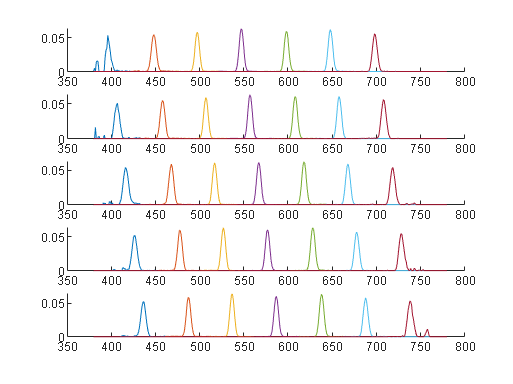

load('OL490_characterization_data.mat','wl_expected','col_input','vec_input','spec_output')

% % visualize
% clf
% hold on
% for comb_i=1:7
%     spec_output{comb_i}.plot
% end


speC_max = spec_output{6};
speC_min = spec_output{7};

for comb_i=1:5
    refl_comb{comb_i} = (spec_output{comb_i}-speC_min)./(speC_max - speC_min);
end

% % visualize
% clf
% hold on
% for comb_i=1:5
%     refl_comb{comb_i}.plot
% end

%
% Break the combs
%
lut35_col = zeros(35,1);
lut35_refl = zeros(35,401);

for comb_i = 1:5
    wl_expected_list = wl_expected{comb_i};
    col_list = col_input{comb_i};
    
    for tooth_j = 1:7
        wl = wl_expected_list(tooth_j);
        col = col_list(tooth_j);
        comb = refl_comb{comb_i}.amplitude;
        tooth = bandpass_at(comb,wl);

        idx = 1 + 5*(tooth_j-1) + (comb_i-1);
        lut35_col(idx,1) = col;
        lut35_refl(idx,:) = tooth;
    end
end

i = 509

i = 509

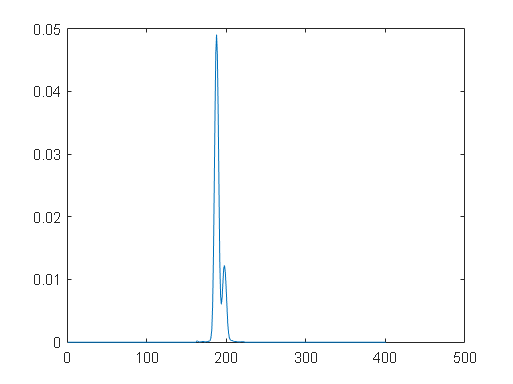

clf
plot(lut_vec2reflectance(i,:))

i = 30

i = 30

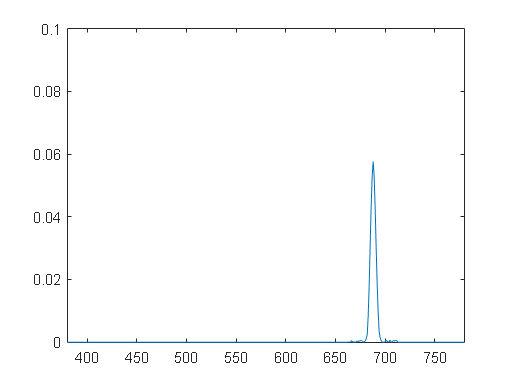

clf
plot(380:780,lut35_refl(i,:))
axis([380 780 0 0.1])


%
% Interpolate from 35 to 1024
%
lut_vec2reflectance = zeros(1024,401);
for wlidx = 1:401
    lut_vec2reflectance(:,wlidx) = interp1(lut35_col(:,1),lut35_refl(:,wlidx),[1:1024]');
end
lut_vec2reflectance(isnan(lut_vec2reflectance)) = 0;


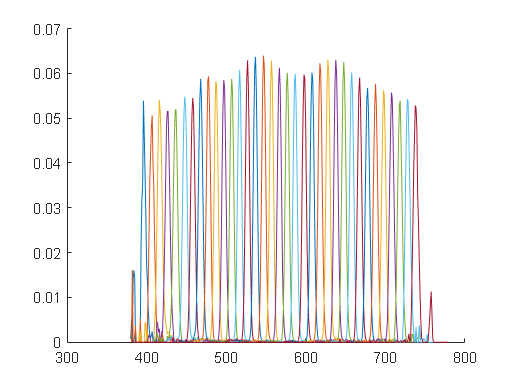

function spec_isolated = bandpass_at (spec,wl_estimated)
    bandwidth = 25;

    % find the max around wl_estimated +/- bandwidth
    wlidx = wl_estimated - 380+1;
    wlidx_start = wlidx-bandwidth;
    wlidx_end = wlidx+bandwidth;
    wlidx_start = max(1,wlidx_start);
    wlidx_end = min(401,wlidx_end);

    spec_temp = spec;
    spec_temp([1:wlidx_start-1 wlidx_end+1:end]) = 0;
    [M I] = max(spec_temp);

    % re-center
    wlidx = I;
    wlidx_start = wlidx-bandwidth;
    wlidx_end = wlidx+bandwidth;
    wlidx_start = max(1,wlidx_start);
    wlidx_end = min(401,wlidx_end);

    spec_isolated = spec;
    spec_isolated([1:wlidx_start-1 wlidx_end+1:end]) = 0;

    % remove negative
    spec_isolated = max(0,spec_isolated);
    

end